## Remember:

% TO section off your code use the %%, then uncomment it.

## EigenShoe runner

Uses all datasets, to create an SVD, and then Categorize shoes.

### Load images

clear
include_O_DS = false;


[IMAGE_DIM, IMAGE_SIZE, num_shoes, LeftShoes, RightShoes, Lookup] = LoadImagesBig( 4 );

Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Ansazi\PXL_20230322_044837612.jpg for left shoe 1 of 16 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Ansazi\PXL_20230322_044840953.jpg for left shoe 2 of 16 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Ansazi\PXL_20230322_044843223.jpg for left shoe 3 of 16 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Ansazi\PXL_20230322_044845565.jpg for left shoe 4 of 16 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Instincts\PXL_20230322_044854468.jpg for left shoe 5 of 16 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Instincts\PXL_20230322_044857318.jpg for left shoe 6 of 16 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Instincts\PXL_20230322_044859618.jpg for left shoe 7 of 16 
Now reading C:\Users\klavl\Documents\GitHub\EigenShoe\REI\Left\Instincts\PXL_20230322_044903888.jpg for left shoe 8 of 16 
Now reading C:\Users\klavl\D


if include_O_DS == true
    names = ["Ansazi", "Instincts", "RedLine", "Spire"];
    [IMAGE_DIM, IMAGE_SIZE, num_shoes2, Shoes, Lookup2] = LoadImages(names, 4);
end

## Construct data into groups

if include_O_DS
    LeftShoes2 = zeros(IMAGE_SIZE, num_shoes2 / 2);
    RightShoes2 = zeros(IMAGE_SIZE, num_shoes2 / 2);
    
    Lookup3 = string(zeros(num_shoes2 / 2, 2));
    for i = 1:num_shoes2
        left = mod(floor((i - 1) / 2), 2) == 0;
        index = floor((i - 1) / 2) + 1;
        if left
            LeftShoes2(:, index) = Shoes(:, i);
            Lookup3(index, 1) = Lookup2(i);
        end
    
        if ~left
            Lookup3(index, 2) = Lookup2(i);
            RightShoes2(:, floor((i - 1) / 2) + 1) = Shoes(:, i);
        end
    
    end

    for i = 1:8
        subplot(2, 4, i)
        l = reshape(LeftShoes2(:, i), [IMAGE_DIM, IMAGE_DIM]);
        imagesc(l), axis off, colormap gray
    end



    Lookup = [Lookup; Lookup3];
    LeftShoes = [LeftShoes LeftShoes2];
    RightShoes = [RightShoes RightShoes2];
    num_shoes = num_shoes + num_shoes2;
    
    Shoes = [LeftShoes RightShoes];
    
    disp("DONE");
    
    clear i left index Lookup2 Lookup3 num_shoes2 LeftShoes2 RightShoes2

else
    Shoes = [LeftShoes RightShoes];
end

## Check left and right

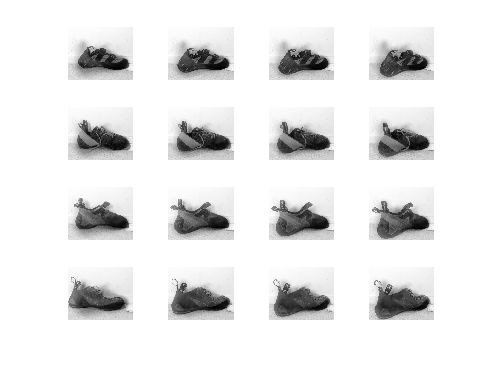

avgShoe = mean(Shoes,2);

for i = 1:16
    subplot(4, 4, i)
    l = reshape(LeftShoes(:, i) + avgShoe, [IMAGE_DIM, IMAGE_DIM]);
    imagesc(l), axis off, colormap gray
end

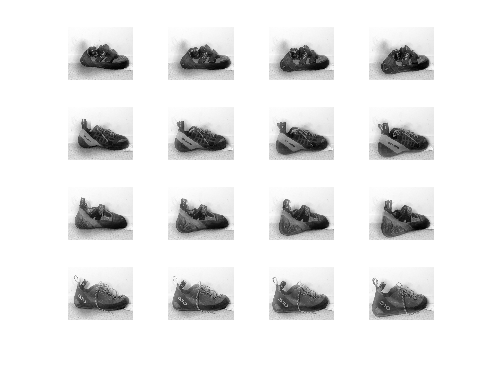


figure()

for i = 1:16
    subplot(4, 4, i)
    r = reshape(RightShoes(:, i) + avgShoe, [IMAGE_DIM, IMAGE_DIM]);
    imagesc(r), axis off, colormap gray
end


clear l r


## Get SVD

Do it around mean subtracted, so we have negative and positive sigma values, centering all of our data.


Shoes = Shoes-avgShoe*ones(1,size(Shoes,2));
[U,S,V] = svd(Shoes,'econ');



norm(Shoes - U * S * V');
disp("How close the svd is to the matrix: " + num2str(ans));

How close the svd is to the matrix: 3.2352e-11


### Plot our SVD and average face

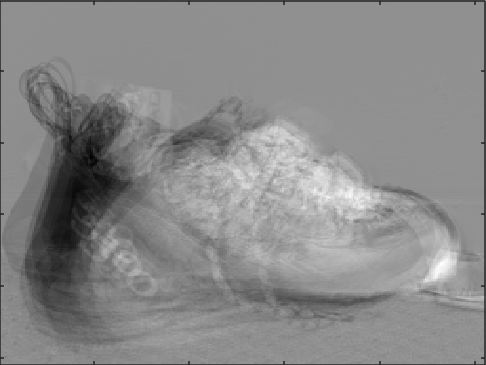

figure(1), axes('position',[0  0  1  1]), axis off
imagesc(reshape(avgShoe, IMAGE_DIM, IMAGE_DIM))
title("avg shoe"), colormap gray;

figure(2), axes('position',[0  0  1  1]), axis off
title("first eigenshoe"), colormap gray;
imagesc(reshape(U(:,1), IMAGE_DIM, IMAGE_DIM))

## Get r values

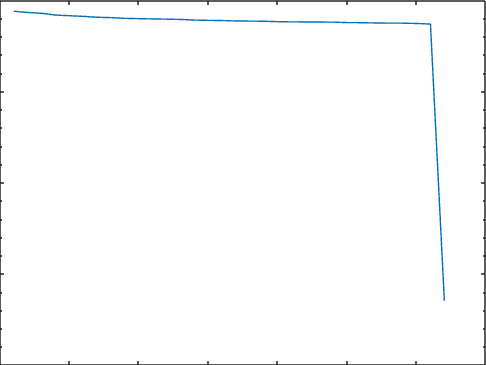

semilogy(diag(S)), grid off
xlabel('r')
ylabel('Singular value, \sigma_r')

## Plot all calculated eigenfaces

n = IMAGE_DIM;
m = IMAGE_DIM;
EigenShoes = zeros(n*3, m*2);
count = 1;
for i = 1:3
    for j = 1:2
        EigenShoes(1+(i-1)*n : i*n , 1+(j-1)*m : j*m) ...
            = reshape(U(:,count), n, m);
%         subplot(3,2, count);
%         imshow((reshape(U(:,count), n, m) + 0) * 500);

        count = count + 1;
    end
end

disp("EGFACE")

EGFACE


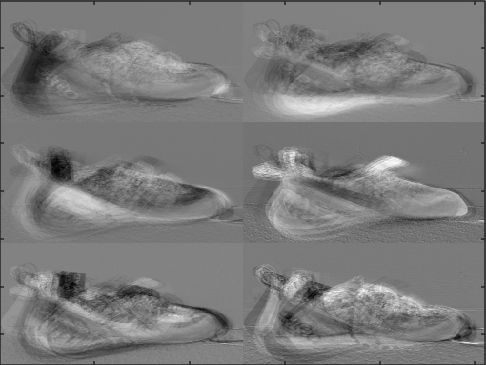

figure(), axes('position',[0  0  1  1]), axis off
imagesc(EigenShoes), colormap gray;

## Now show eigenface reconstruction of image that was omitted from test set

close all

testLeft = true

testLeft = logical
   1



disp("TRY RECONSTRUCING THIS USING EIGENFACES")

TRY RECONSTRUCING THIS USING EIGENFACES


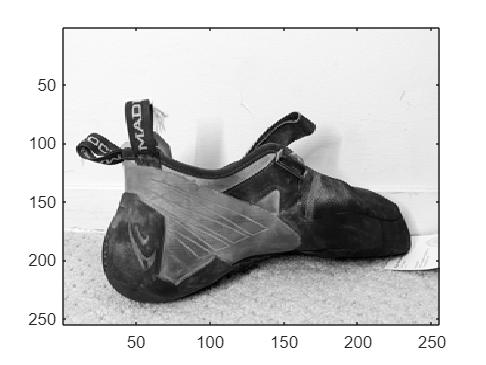

if testLeft == false
    testShoe = imread("TestLR/Instinct.jpg");
else
    testShoe = imread("TestLR/Ansazi.jpg");
end
testShoe = im2gray(testShoe);
testShoe = imresize(testShoe, [IMAGE_DIM, IMAGE_DIM]);
imagesc(reshape(testShoe,n,m)), colormap gray

testShoe = reshape(double( im2gray(testShoe) ) , IMAGE_SIZE, 1);


disp("WOW! It used knowledge of other shoes to approximate this!")

WOW! It used knowledge of other shoes to approximate this!


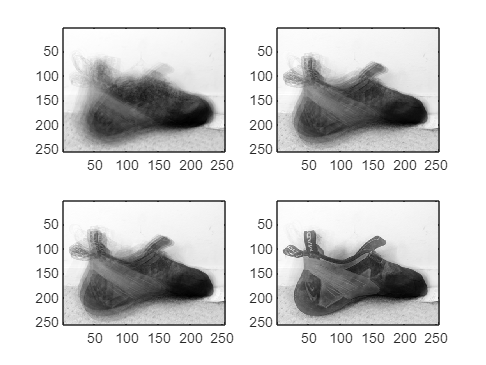

testShoeCentred = testShoe - avgShoe;
count = 1;
for r=[2 5 10 32] 
    reconShoe = avgShoe + (U(:,1:r)*(U(:,1:r)'*testShoeCentred));
    subplot(2,2, count);
    imagesc(reshape(reconShoe + avgShoe,n,m))
%     figure(count), axes('position',[0  0  1  1]), axis off
%     title(['r=',num2str(r, "%d")])
    count = count + 1;
end

## Build our shoes and display them

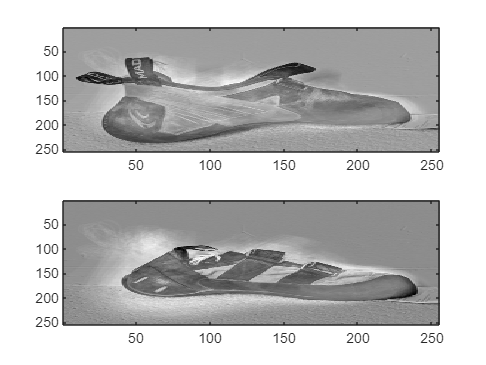

figure()
subplot(2, 1, 1)
imagesc(reshape(testShoeCentred,n,m)), colormap gray
hold on

test2 = LeftShoes(:, 1) - avgShoe;
subplot(2, 1, 2)
imagesc(reshape(test2,n,m)), colormap gray

## Show how right and left shoes are different, build a classifier

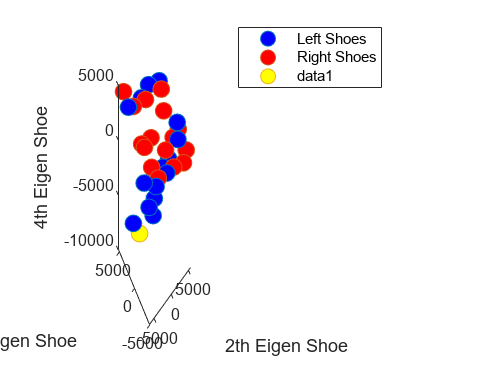

close all
% Project the All shoes onto 3 eigen shoes

Eigens = [2, 3, 4];



Left_Plot = zeros(3, size(LeftShoes, 2));

% normalize and get its multiplier of the eigenvalues of left shoes
for i = 1:size(LeftShoes, 2)
    LeftShoes(:, i) = LeftShoes(:, i) - avgShoe;
    Left_Plot(:, i) = LeftShoes(:, i)' * U(:, Eigens);
end

Right_Plot = zeros(3, size(RightShoes, 2));

% right shoes
for i = 1:size(RightShoes, 2)
    RightShoes(:, i) = RightShoes(:, i) - avgShoe;
    Right_Plot(:, i) = RightShoes(:, i)' * U(:, Eigens);
end

figure()
plot3(Left_Plot(1, :), Left_Plot(2, :), Left_Plot(3, :), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'b')
hold on
plot3(Right_Plot(1, :), Right_Plot(2, :), Right_Plot(3, :), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'r')
xlabel(string(Eigens(1, 1)) + 'th Eigen Shoe')
ylabel(string(Eigens(1, 2)) + 'th Eigen Shoe')
zlabel(string(Eigens(1, 3)) + 'th Eigen Shoe')
legend('Left Shoes', 'Right Shoes')

% Overlay my right instinct shoe and see where it lives

testPts = testShoeCentred' * U(:, Eigens);
plot3(testPts(1), testPts(2), testPts(3), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'y')

Notes: The classifier is really difficult to pull off, since these shoes look so similar to one another, it would even be hard for a human to tell a right from a left. However it is still obvious that the data point lives right in the middle of the red points. An obvious red.

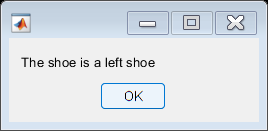


% Calculate the distance between the test shoe and all the left shoes
% Calculate the distance between the test shoe and all the right shoes
% determine which is closer
% display the result

dist_right = 0;
dist_left = 0;

for i = 1:size(Left_Plot, 2)
    dist_left = dist_left + norm(testPts - Left_Plot(:, i));
end

for i = 1:size(Right_Plot, 2)
    dist_right = dist_right + norm(testPts - Right_Plot(:, i));
end

% make a matlab popup
if dist_left < dist_right
    msgbox('The shoe is a left shoe')
else
    msgbox('The shoe is a right shoe')
end